- Diffusion LMS:-

Steady state:

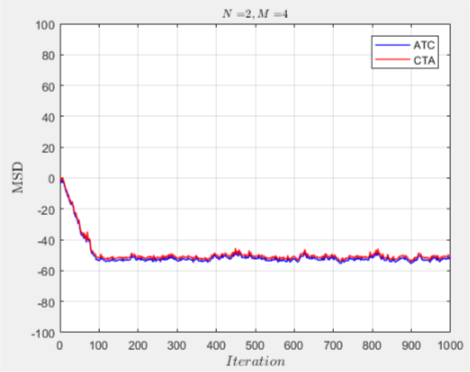

Transient:

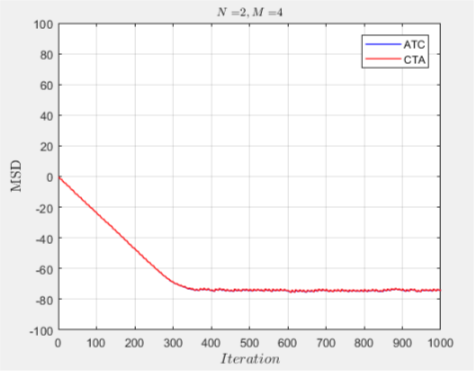

2. LMS

Steady state:

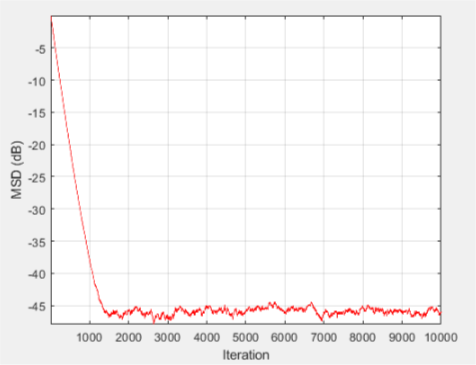

Transient state:

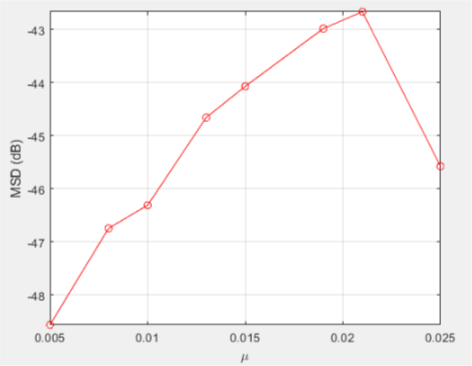

3. Comparison between steady LMS,KLMS,MCC,KMCC

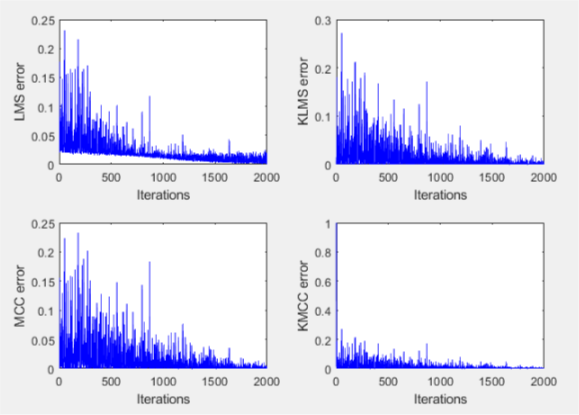

Codes:-

1: Steady state

for L=1:Num_trial % iterating over experiments

    % ATC initialization
    psi = zeros(M,N);           % psi column vectors for all agents in the ATC network
    w   = zeros(M,N);           % iterate column vectors for all agents in the ATC network
    tilde_w   = zeros(M,N);     % error column vectors for all agents in the ATC network

    % CTA initialization
    psi_CTA = zeros(M,N);       % psi column vectors for all agents in the CTA network
    w_CTA   = zeros(M,N);       % iterate column vectors for all agents in the CTA network
    tilde_w_CTA = zeros(M,N);   % error column vectors for all agents in the CTA network

    for i=1:Num_iter 

       for k=1:N % CTA
           psi_CTA(:,k) = zeros(M,1);
           for l=1:N
              psi_CTA(:,k) = psi_CTA(:,k) + A(l,k)*w_CTA(:,l); 
           end
       end
       
       for k=1:N
          if h==1 
            uk = randn(1,M)*diag(sqRU(:,k));
            dk = uk*wo + randn*sqrt(sigma_v2(k));
          else
            uk = complexrandn(1,M)*diag(sqRU(:,k)); % Gaussian row regression vector 
            dk = uk*wo + complexrandn(1,1)*sqrt(sigma_v2(k));
          end
          psi(:,k)    = w(:,k) + (2/h)*mu(k)*uk'*(dk - uk*w(:,k));                       
          w_CTA(:,k)  = psi_CTA(:,k) + (2/h)*mu(k)*uk'*(dk - uk*psi_CTA(:,k)); 
       end
       
       for k=1:N 
           w(:,k) = zeros(M,1);
           for l=1:N
              w(:,k) = w(:,k) + A(l,k)*psi(:,l); 
           end
           tilde_w(:,k) = wo - w(:,k); % ATC
           MSD_agent(k,i) = MSD_agent(k,i) + (norm(tilde_w(:,k),2))^2; 

           tilde_w_CTA(:,k) = wo - w_CTA(:,k); % CTA
           MSD_agent_CTA(k,i) = MSD_agent_CTA(k,i) + (norm(tilde_w_CTA(:,k),2))^2;        
         

       end       
   end
end

Transient:

for L=1:Num_trial 

    % ATC initialization
    psi = zeros(M,N);           
    w   = zeros(M,N);          
    tilde_w   = zeros(M,N);     

    % CTA initialization
    psi_CTA = zeros(M,N);       
    w_CTA   = zeros(M,N);     
    tilde_w_CTA = zeros(M,N);   

    for i=1:Num_iter  % iterating over time

       for k=1:N % CTA
           psi_CTA(:,k) = zeros(M,1);
           for l=1:N
              psi_CTA(:,k) = psi_CTA(:,k) + A(l,k)*w_CTA(:,l); % CTA diffusion (consultation step)
           end
       end
       
       for k=1:N % generate data for each agent at time i
          if h==1 % real data 
            uk = randn(1,M)*diag(sqRU(:,k)); % Gaussian row regression vector 
            dk = uk*wo + randn*sqrt(sigma_v2(k));
          else
            uk = complexrandn(1,M)*diag(sqRU(:,k)); % Gaussian row regression vector 
            dk = uk*wo + complexrandn(1,1)*sqrt(sigma_v2(k));
          end
          psi(:,k)    = w(:,k) + (2/h)*mu1(mod(i,10)+1)*uk'*(dk - uk*w(:,k));                     
          w_CTA(:,k)  = psi_CTA(:,k) + (2/h)*mu1(mod(i,10)+1)*uk'*(dk - uk*psi_CTA(:,k));
       end
       
       for k=1:N 
           w(:,k) = zeros(M,1);
           for l=1:N
              w(:,k) = w(:,k) + A(l,k)*psi(:,l); 
           end
           tilde_w(:,k) = wo - w(:,k); % ATC
           MSD_agent(k,i) = MSD_agent(k,i) + (norm(tilde_w(:,k),2))^2; 

           tilde_w_CTA(:,k) = wo - w_CTA(:,k); % CTA
           MSD_agent_CTA(k,i) = MSD_agent_CTA(k,i) + (norm(tilde_w_CTA(:,k),2))^2;            

       end       
   end
end

2. 

 N = 10000;  % number of iterations
 
 M = 5; % number of taps
 wo = randn(M,1);
 wo = wo/norm(wo);

 var_n = 0.001; % Gaussian noise
 sqn   = sqrt(var_n);

 mu = 0.01;

 rho = 5;  % desired eigenvalue spread
 lambda_min = 1;   % generate positive eigenvalues in the interval
 lambda_max = rho; % [lambda_min; lambda_max];
 eigenv = lambda_min + (lambda_max-lambda_min)*rand(M-2,1);
 R = diag([lambda_min;eigenv;lambda_max]); % Covariance matrix; it is diagonal = Lambda
 sqR = sqrt(R);

 Lambda = R; % Since R is diagonal; therefore U = I in this problem
 lambda = [lambda_min;eigenv;lambda_max]; % a column of eigenvalues
  
 F_bar = (eye(M,M) - 2*mu*Lambda + mu^2*Lambda^2) + mu^2*lambda*lambda';
 wo_bar = wo;
 
 msd(1) = norm(wo)^2; % time indexing starts at 1 in matlab!
 Fa = eye(M,M);
 for i=1:N-1
   W1 = diag(Fa*(eye(M,M)-F_bar)*ones(M,1)); % undo the vec operation to generate the weight matrix
   b = mu*mu*var_n*(lambda'*Fa)*ones(M,1);
   c = wo_bar'*W1*wo_bar;    
   msd(i+1) = msd(i) + b - c; % theoretical MSD curve for LMS
   Fa =  F_bar*Fa;
end

L = 30;

w  = zeros(M,1); % initial weight estimate
u  = zeros(1,M); % initial regressor

      
msd_curve_sim = zeros(1,N); % simulated MSD curve
       
for j=1:L % iteration over learning curves
   w = zeros(M,1);
   nw = zeros(1,N);
   
   for i=1:N  
     nw(i) = norm(wo-w)^2;
     u = randn(1,M)*sqR; % regressor
     for j = 1:length(u)
        u(j) = u(j)/((1+u(j)^2)^0.5);
     end
     d = u*wo + sqn*randn; % reference
     error = d - u*w; % error
     w = w + mu*u'*error;  % LMS recursion
   end
        
   msd_curve_sim = msd_curve_sim + nw;
end

msd_curve_sim  = msd_curve_sim/L;

msd_value  = mean(msd_curve_sim(N-200:N))

a=0;
b=0;
for i=1:M
  a = a + 1/(2-mu*lambda(i))  ;
  b = b + lambda(i)/(2-mu*lambda(i))  ;
end

  
msd_thy = mu*var_n*a/(1-mu*b)


figure
plot(1:N,10*log10(msd_curve_sim),'r')
xlabel('Iteration');
ylabel('MSD (dB)');
%legend('Simulation');
axis tight
grid

w  = zeros(M,1); % initial weight estimate
u  = zeros(1,M); % initial regressor

mu_vec = [0.025 0.021 0.019 0.015 0.013 0.010 0.008 0.005];
K = length(mu_vec);

aux = msd_value;
msd_value = zeros(1,K);
msd_value(1) = aux;
aux = msd_thy;
msd_thy = zeros(1,K);
msd_thy(1) = aux;

for kk=2:K
   
  mu = mu_vec(kk)
  msd_curve_sim = zeros(1,N); % simulated MSD curve
       
  for j=1:L % iteration over learning curves
    w = zeros(M,1);
    nw = zeros(1,N);
   
    for i=1:N  
      nw(i) = norm(wo-w)^2;
      u = randn(1,M)*sqR; % regressor
      for j = 1:length(u)
        u(j) = u(j)/((1+u(j)^2)^0.5);
      end
      d = u*wo + sqn*randn; % reference
      error = d - u*w; % error
      w = w + mu*u'*error;  % LMS recursion
    end
        
    msd_curve_sim = msd_curve_sim + nw;
  end

  msd_curve_sim  = msd_curve_sim/L;
  msd_value(kk)  = mean(msd_curve_sim(N-200:N))
  a=0;
  b=0;
  for i=1:M
    a = a + 1/(2-mu*lambda(i));
    b = b + lambda(i)/(2-mu*lambda(i));
  end
  msd_thy(kk) = mu*var_n*a/(1-mu*b)
end


for kk=1:K
    f(kk)=0;
    for i=1:M
     f(kk) = f(kk) + mu_vec(kk)*lambda(i)/(1-mu_vec(kk)*lambda(i));
    end
    f(kk) = (1/2)*f(kk);
end


figure
plot(mu_vec,10*log10(msd_value),'ro-');
xlabel('\mu')
ylabel('MSD (dB)')
axis tight
grid

3.

nodes = input('Enter no. of nodes:');
iters=input('Enter no. of iterations:');
data = randn(nodes,iters);

y = sign(randn(1,nodes)*data);
x = data + 10^(-30/20)*randn(size(data));

round_no=input('Enter no. of rounds:');

for rounds =1:round_no
    rounds
    [y, mse_lms(rounds,:)] = lms(x, y, nodes, iters);
    [y1, mse_klms(rounds,:)] = klms(x, y, nodes, iters);
    [y2, mse_mcc(rounds,:)] = mcc(x, y, nodes, iters);
    [y3, mse_kmcc(rounds,:)] = kmcc(x, y, iters);
end
y(y > 0) = 1; 
y(y <= 0) = -1;

y1(y1 > 0) = 1; 
y1(y1 <= 0) = -1;

t = 0:iters-1;
subplot(2,2,1);
plot(t, mean(mse_lms),'b-');
xlabel('Iterations'), ylabel('LMS error');
subplot(2,2,2);
plot(t, mean(mse_klms),'b-');
xlabel('Iterations'), ylabel('KLMS error');
subplot(2,2,3);
plot(t, mean(mse_mcc),'b-');
xlabel('Iterations'), ylabel('MCC error');
subplot(2,2,4);
plot(t, mean(mse_kmcc),'b-');
xlabel('Iterations'), ylabel('KMCC error');


function [y, mse] = lms(u, d, M, N)  
    mu = 0.001;
    w = zeros(1,M);
    for i = 1:N
        e(i) = d(i) - w * u(:,i);
        w = w + mu * e(i) * (u(:,i)');
        mse(i) = abs(e(i))^2;
    end
    y=(w * u);
    
end


function [y, mse] = klms(u, d, M, N)
    mu = 0.1;
    sigma = 0.004;
    e = d;
    y(1) = mu * e(1) * exp((-e(1)^2) / (2*sigma^2));
    mse(1) = 0;
    for n = 2:N
        i = 1:(n-1);
        y(n) = mu * e(i)*(exp(- sigma * sum((u(:,i)-u(:,n)).^2)))';
        e(n) = d(n) - y(n);
        mse(n) = abs(e(n))^2;
    end  
end


function [y, mse] = mcc(u, d, M, N)  
    mu = 0.001;
    sigma = 1;
    w = zeros(1,M);
    for i = 1:N
        e(i) = d(i) - w * u(:,i);
        w = w + mu * exp(- sigma * sum(e(i)).^2) * e(i) * (u(:,i)');
        mse(i) = abs(e(i))^2;
    end
    y=(w * u);    
end


function [y, mse] = kmcc(u, d, N)
    mu = 0.1;
    sigma = .004;
    e = d;
    y(1) = mu * e(1) * exp(- sigma * e(1) ^2);
    mse(1) = 1;
    for n = 2:N
        i = 1:(n-1);
        y(n) = mu * e(i)* exp(- sigma * sum(e(i)).^2) * (exp(- sigma * sum((u(:,i)-u(:,n)).^2)))';
        e(n) = d(n) - y(n);
        mse(n) = abs(e(n))^2;
    end  
end